# ME5554/AOE5754/ECE5754 Applied Linear Systems - Midterm Project

Sam Kramer

October 29th, 2023

% --Setup
    clear; clc; format compact; close all;

## Background

A small startup company is exploring an aerial concept for delivering packages (Payload).  This concept uses an open-top bin (gray) supported by drone motors and propellors (blue-forward and green-aft).

Prior to developing a full 3D prototype, they have commissioned you to develop and validate a full state feedback control system for a 2D (i.e. planar) version as shown in Figure 1.

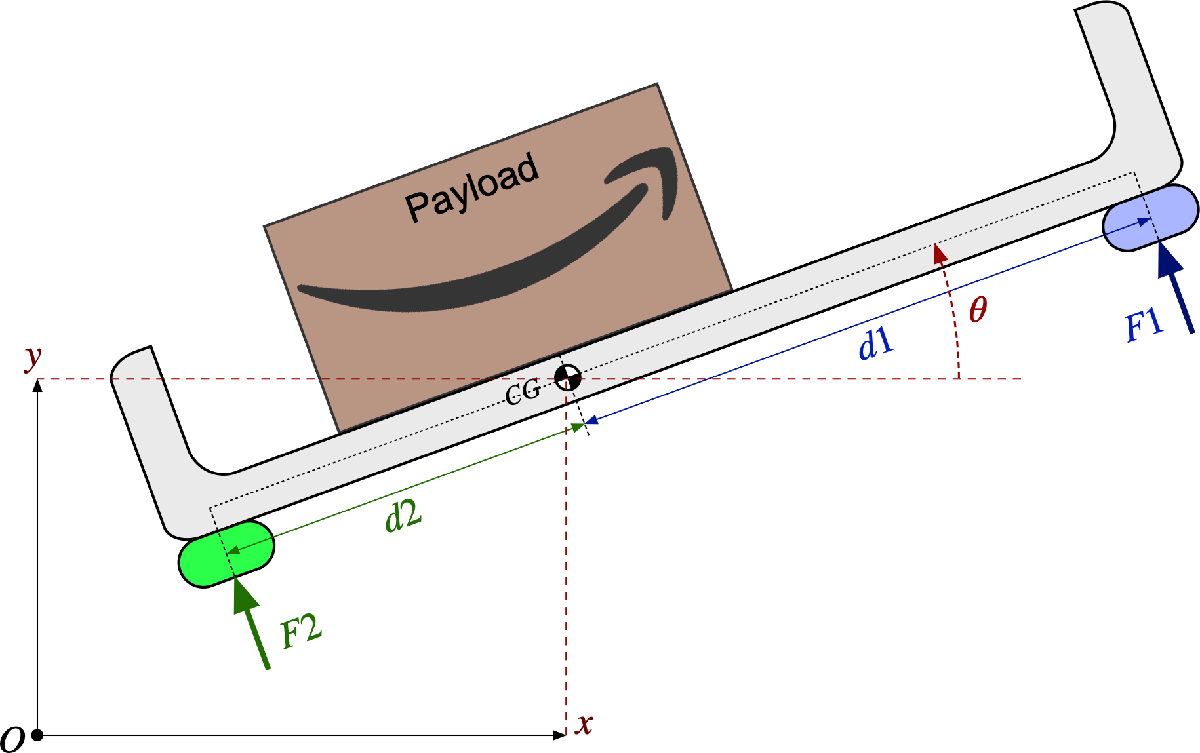

**Figure 1.  2D-Coordinate System Definition for Prototype Aerial Package Delivery System**

The following definitions refer to Figure 1:

        
$$\begin{array}{l}
\textrm{CG}=\textrm{center}\;\textrm{of}\;\textrm{gravity}\;\textrm{of}\;\textrm{the}\;\textrm{system}\;\textrm{with}\;\textrm{the}\;\textrm{current}\;\textrm{payload}\;\textrm{position}\\
O=\textrm{origin}\;\textrm{of}\;\textrm{the}\;\textrm{world}\;\textrm{coordinate}\;\textrm{system}\\
x\left(t\right)=\textrm{horizontal}\;\textrm{position}\;\left\lbrack m\right\rbrack \;\textrm{of}\;\textrm{the}\;\textrm{CG}\;\textrm{in}\;\textrm{the}\;\textrm{world}\;\textrm{coordinate}\;\textrm{system}\\
y\left(t\right)=\textrm{vertical}\;\textrm{position}\;\left\lbrack m\right\rbrack \;\textrm{of}\;\textrm{the}\;\textrm{CG}\;\textrm{in}\;\textrm{the}\;\textrm{world}\;\textrm{coordinate}\;\textrm{system}\\
\theta \left(t\right)=\textrm{angular}\;\textrm{rotation}\;\left\lbrack \textrm{rad}\right\rbrack \;\textrm{of}\;\textrm{the}\;\textrm{open}-\textrm{top}\;\textrm{bin}\\
F_1 \left(t\right)=\textrm{bipolar}\;\textrm{control}\;\textrm{thrust}\;\textrm{force}\;\left\lbrack N\right\rbrack \;\textrm{at}\;\textrm{the}\;\textrm{front}\;\textrm{of}\;\textrm{the}\;\textrm{bin}\\
F_2 \left(t\right)=\textrm{bipolar}\;\textrm{control}\;\textrm{thrust}\;\textrm{force}\;\left\lbrack N\right\rbrack \;\textrm{at}\;\textrm{the}\;\textrm{rear}\;\textrm{of}\;\textrm{the}\;\textrm{bin}
\end{array}$$


The equations of motion for this system are non-linear; however, the following linearized equations are a reasonable approximation for the purposes of this project:

- Force balance, y-direction:      $M\ddot{\mathrm{y}} \left(t\right)=F_1 \left(t\right)+F_2 \left(t\right)-\alpha \dot{y} \left(t\right)-M\;g\;$  

- Moment balance about CG:    $J\ddot{\theta} \left(t\right)=d_1 F_1 \left(t\right)-d_2 F_2 \left(t\right)-\beta \dot{\theta} \left(t\right)$  

- Force balance, x-direction:     $M\ddot{x} \left(t\right)=-\left({\bar{F} }_1 +{\bar{F} }_2 \right)\theta \left(t\right)-\gamma \dot{x} \left(t\right)$ 

The parameters associated with these dynamic equations are defined as:

        
$$\begin{array}{l}
g=\textrm{gravity}\;\left\lbrack \frac{m}{s^2 }\right\rbrack \\
M=\textrm{total}\;\textrm{mass}\;\left\lbrack \textrm{kg}\right\rbrack \;\textrm{of}\;\textrm{the}\;\textrm{system}\;\textrm{with}\;\textrm{payload}\\
J=\textrm{total}\;\textrm{rotational}\;\textrm{moment}\;\textrm{of}\;\textrm{inertia}\;\left\lbrack \textrm{kg}\cdot m^2 \right\rbrack \;\textrm{about}\;\textrm{the}\;\textrm{CG}\;\textrm{of}\;\textrm{the}\;\textrm{system}\;\textrm{with}\;\textrm{payload}\\
\alpha =\textrm{vertical}\;\textrm{aerodynamic}\;\textrm{damping}\;\textrm{coefficient}\;\;\left\lbrack \frac{N\cdot s}{\;m}\right\rbrack \\
\beta =\textrm{rotational}\;\textrm{aerodynamic}\;\textrm{damping}\;\textrm{coefficient}\;\left(\frac{N\cdot m\cdot s}{\textrm{rad}}\right)\\
\gamma =\textrm{horizontal}\;\textrm{aerodynamic}\;\textrm{damping}\;\textrm{coefficient}\;\left(\frac{N\cdot s}{m}\right)\\
d_1 =\textrm{distance}\;\left\lbrack m\right\rbrack \;\textrm{from}\;\textrm{the}\;\textrm{CG}\;\textrm{to}\;\textrm{the}\;\textrm{front}\;\textrm{control}\;\textrm{thrust}\\
d_2 =\textrm{distance}\;\left\lbrack m\right\rbrack \;\textrm{from}\;\textrm{the}\;\textrm{CG}\;\textrm{to}\;\textrm{the}\;\textrm{rear}\;\textrm{control}\;\textrm{thrust}
\end{array}$$


## Problem 1 [4 pts].  Equilibrium Thrust Forces

Notice from the x-direction force balance equation that two variables were introduced.  These variables are defined as:

        
$$\begin{array}{l}
{\bar{F} }_1 =\textrm{the}\;\textrm{nominal}\;\textrm{or}\;\textrm{steady}-\textrm{state}\;\textrm{nonzero}\;\textrm{front}\;\textrm{thrust}\;\left\lbrack N\right\rbrack \;\textrm{to}\;\textrm{maintain}\;\textrm{an}\;\textrm{equilibrium}\;\textrm{hover}\;\textrm{condition}\\
{\bar{F} }_2 =\textrm{the}\;\textrm{nominal}\;\textrm{or}\;\textrm{steady}-\textrm{state}\;\textrm{nonzero}\;\textrm{rear}\;\textrm{thrust}\;\left\lbrack N\right\rbrack \;\textrm{to}\;\textrm{maintain}\;\textrm{an}\;\textrm{equilibrium}\;\textrm{hover}\;\textrm{condition}
\end{array}$$


Derive an analytic formula (i.e. an equation without specific numerical parameter values) relating these two nominal **equilibrium** thrust values to the system parameters. 

Hint:  When the system is in Equilibrium, all derivatives in the ODE's must be zero!

I have elected to do the math for this problem through the latex editor because it is cleaner and easier to follow.

Lets set up the problem, and set the derivatives in the system equal to zero, and then lets standardize the variable terms for the forces. We are able to do this because we are only interested in the steady-state case and therefore can remove all time dependencies in the force variables.


$$F_1(t) = \bar{F_1}=F_1$$



$$F_2(t) = \bar{F_2}=F_2$$



$$M\ddot{\gamma}(t) = 0 = -(F_1 + F_2)(\Theta(t))$$



$$0=d_1 F_1 \left(t\right)-d_2 F_2 \left(t\right)$$



$$0=F_1 \left(t\right)+F_2 \left(t\right)-M\;g\;$$



$$\begin{cases} 0=F_1+F_2 \\ 0=d_1F_1-d_2F_2 \\ 0=F_1+F_2-Mg \end{cases}$$



$$\begin{cases} F_1 = -F_2 \\ F_1=\frac{d_2}{d_1}F_2\\ F_1 = Mg-F_2 \end{cases}$$


Throw out first case because it does not provide useful information. This yields the following equation set with two unknowns, $F_1$ and $F_2$ in terms of other parameters in the system.


$$\begin{cases} F_1 = \frac{d_2}{d_1}F_2 \\ F_1 = Mg-F_2\end{cases}$$


Solve for $F_2$:


$$Mg -F_2 = \frac{d_2}{d_1}F_2$$



$$Mg = F_2 + \frac{d_2}{d_1}F_2$$



$$F_2 = \frac{Mg}{1+\frac{d_2}{d_1}}$$


Solving for $F_1$:


$$F_1 = \frac{d_2}{d_1}F_2$$



$$F_1 = \frac{d_2}{d_1}\frac{Mg}{1+\frac{d_2}{d_1}}$$



$$F_1 = \frac{Mg\frac{d_2}{d_1}}{1+\frac{d_2}{d_1}}$$


Therefore, we have found the equilibrium forces for the system and can be defined as the following:

 
$$\begin{cases} \bar{F_1} = \frac{Mg\frac{d_2}{d_1}}{1+\frac{d_2}{d_1}} \\ \bar{F_2} = \frac{Mg}{1+\frac{d_2}{d_1}} \end{cases}$$


## Problem 2 [6 pts].  Equations of Motion around the Operating Point

We now want to eliminate the equilibrium forces ${\bar{F} }_1$ and ${\bar{F} }_2$ from the equations of motion.  To do this, we can introduce what are known as "variational forces", which are simply zero-mean forces $u_1$ and $u_2$ which are added to the equilibrium forces to get the total forces:

    
$$F_1 \left(t\right)={\bar{F} }_1 +u_1 \left(t\right)$$
 

    
$$F_2 \left(t\right)={\bar{F} }_2 +u_2 \left(t\right)$$
 

Substitute these definitions into the equations of motion and eliminate the equilibrium forces.  Your new equations of motion must not have any equilibrium forces remaining and must only include the variational force inputs.

I have elected to do the math for this problem through the latex editor because it is cleaner and easier to follow.

Redefine our variables for the forces:


$$\begin{cases}  F_1(t) = \bar{F_1} +U_1(t) \\ F_2(t) = \bar{F_2} +U_2(t) \end{cases}$$



$$\begin{cases} 

F_1(t)= \frac{Mg\frac{d_2}{d_1}}{1+\frac{d_2}{d_1}} + u_1(t) 

\\ 

F_2 (t)= \frac{Mg}{1+\frac{d_2}{d_1}} + u_2(t)

\end{cases}$$


Plug new force definitions into our system of equations:


$$\begin{cases} 

M\ddot{y}(t) = \bar{F_1}+u_1(t) + \bar{F_2} +u_2(t) -\alpha\dot{y}(t)-Mg

\\

J\ddot{\Theta}=d_1(\bar{F_1}+u_1(t)) -d_2(\bar{F_2}+u_2(t)) -\beta\dot{\Theta}

 \\ 

M\ddot{x} = -(\bar{F_1} +\bar{F_2})\Theta(t) -\gamma\dot{x}(t)

\end{cases}$$



$$\begin{cases} 

M\ddot{y}(t) = \frac{Mg\frac{d_2}{d_1}}{1+\frac{d_2}{d_1}}+u_1(t) + \frac{Mg}{1+\frac{d_2}{d_1}}  +u_2(t) -\alpha\dot{y}(t)-Mg

\\

J\ddot{\Theta}=d_1(\frac{Mg\frac{d_2}{d_1}}{1+\frac{d_2}{d_1}}+u_1(t)) -d_2(\frac{Mg}{1+\frac{d_2}{d_1}} +u_2(t)) -\beta\dot{\Theta}

 \\ 

M\ddot{x} = -(\frac{Mg\frac{d_2}{d_1}}{1+\frac{d_2}{d_1}}+\frac{Mg}{1+\frac{d_2}{d_1}} )\Theta(t) -\gamma\dot{x}(t)

\end{cases}$$


Which we are able to simplify because we have from part one that $\bar{F_1} + \bar{F_2} = Mg$ and can distribute out the distances in the second moment balance equation: 


$$\begin{cases} 

M\ddot{y}(t) = u_1(t) +u_2(t) -\alpha\dot{y}(t)

\\

J\ddot{\Theta}=d_1(\frac{Mg\frac{d_2}{d_1}}{1+\frac{d_2}{d_1}}+u_1(t)) -d_2(\frac{Mg}{1+\frac{d_2}{d_1}} +u_2(t)) -\beta\dot{\Theta}

 \\ 

M\ddot{x} = -Mg\Theta(t) -\gamma\dot{x}(t)

\end{cases}$$



$$\begin{cases} 

M\ddot{y}(t) = u_1(t) +u_2(t) -\alpha\dot{y}(t)

\\

J\ddot{\Theta}=\frac{Mgd_2}{1+\frac{d_2}{d_1}}+d_1u_1(t) -\frac{Mgd_2}{1+\frac{d_2}{d_1}} - d_2u_2(t) -\beta\dot{\Theta}

 \\ 

M\ddot{x} = -Mg\Theta(t) -\gamma\dot{x}(t)

\end{cases}$$


Which yields our final set of equations where the fources have been removed and replaced by the inputs to the system $u_1(t)$ and $u_2(t)$:


$$\begin{cases} 

M\ddot{y}(t) = u_1(t) +u_2(t) -\alpha\dot{y}(t)

\\

J\ddot{\Theta}=d_1u_1(t) -d_2u_2(t) -\beta\dot{\Theta}

 \\ 

M\ddot{x} = -Mg\Theta(t) -\gamma\dot{x}(t)

\end{cases}$$


## Problem 3 [6 pts].  Analytic State-Space Model

Using the equations of motion from Problem 2, choose appropriate state variables and define a complete state-space representation for this system.

You must assume that the outputs are $\left(x,y,\theta \right)$ because these can be measured with a GPS sensor, and the inputs must be $\left(u_1 ,u_2 \right)$.

Our given set of equations for the problem:


$$\begin{cases} 

M\ddot{y}(t) = u_1(t) +u_2(t) -\alpha\dot{y}(t)

\\

J\ddot{\Theta}=d_1u_1(t) -d_2u_2(t) -\beta\dot{\Theta}

 \\ 

M\ddot{x} = -Mg\Theta(t) -\gamma\dot{x}(t)

\end{cases}$$


There are many candidate states, the ones I will chose are $\dot{x}, \dot{y}, \dot{\theta}, x, y, \theta$. This is what our state representation will be for our system:


$$\begin{cases} \dot{x} = x_1 \\ \dot{y} = x_2 \\ \dot{\theta} = x_3 \\ x = x_4 \\ y = x_5 \\ \theta = x_6 \end{cases}$$


Plug new states into the ODEs we have defined in problem 2:


$$\begin{cases} 

M\dot{x_1} = -Mgx_6-\gamma x_1

\\

M\dot{x_2} = u_1 +u_2 -\alpha x_2


 \\ 

J\dot{x_3}=d_1u_1 -d_2u_2 -\beta x_3

\\

\dot{x_4} = x_1

\\

\dot{x_5} = x_2

\\

\dot{x_6} = x_3

\end{cases}$$



$$\begin{cases} 

\dot{x_1} = -\frac{\gamma}{M} x_1 - gx_6

\\

\dot{x_2} = \frac{1}{M}(u_1 + u_2)- \frac{\alpha}{M} x_2


 \\ 

\dot{x_3}= \frac{1}{J} (d_1u_1 -d_2u_2) - \frac{\beta}{J}x_3

\\

\dot{x_4} = x_1

\\

\dot{x_5} = x_2

\\

\dot{x_6} = x_3

\end{cases}$$


We are now able to construct the state matrix for our system using the above system of equations:


$$\left\lbrack \begin{array}{c}
\dot{x_1 } \\
\dot{x_2 } \\
\dot{x_3 } \\
\dot{x_4 } \\
\dot{x_5 } \\
\dot{x_6 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccccc}
-\gamma /M & 0 & 0 & 0 & 0 & -g\\
0 & -\alpha /M & 0 & 0 & 0 & 0\\
0 & 0 & -\beta /J & 0 & 0 & 0\\
1 & 0 & 0 & 0 & 0 & 0\\
0 & 1 & 0 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 \\
x_5 \\
x_6 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & 0\\
\frac{1}{M} & \frac{1}{M}\\
\frac{d_1 }{J} & \frac{d_2 }{J}\\
0 & 0\\
0 & 0\\
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
u_1  & u_2 
\end{array}\right\rbrack$$


Our output equation is then given by the following matrix equation:


$$\left\lbrack \begin{array}{c}
y_1 \\
y_2 \\
y_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccccc}
0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 1 & 0\\
0 & 0 & 0 & 0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 \\
x_5 \\
x_6 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0\\
0 & 0\\
0 & 0\\
0 & 0\\
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
u_1  & u_2 
\end{array}\right\rbrack$$


Which will allow us to sense $x_4 = x, x_5 = y, x_6 = \theta$ from the system. Our full state-space realization is given by:


$$\left\lbrack \begin{array}{c}
\dot{x_1 } \\
\dot{x_2 } \\
\dot{x_3 } \\
\dot{x_4 } \\
\dot{x_5 } \\
\dot{x_6 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccccc}
-\gamma /M & 0 & 0 & 0 & 0 & -g\\
0 & -\alpha /M & 0 & 0 & 0 & 0\\
0 & 0 & -\beta /J & 0 & 0 & 0\\
1 & 0 & 0 & 0 & 0 & 0\\
0 & 1 & 0 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 \\
x_5 \\
x_6 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & 0\\
\frac{1}{M} & \frac{1}{M}\\
\frac{d_1 }{J} & \frac{d_2 }{J}\\
0 & 0\\
0 & 0\\
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
u_1  & u_2 
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{c}
y_1 \\
y_2 \\
y_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccccc}
0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 1 & 0\\
0 & 0 & 0 & 0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 \\
x_5 \\
x_6 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0\\
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
u_1  & u_2 
\end{array}\right\rbrack$$


## Problem 4 [2 pts].  Define system parameters as Matlab variables

Up to this point, you have only used algebraic symbols to describe parameters in the state-space model.  It is now time to substitute numerical values for these parameters.  Define variables in Matlab for the following parameters:

        
$$\begin{array}{l}
g=9\ldotp 81\;\left(m/s^2 \right)\\
M=10\;\left(\textrm{kg}\right)\;\\
J=5\;\left(\textrm{kg}\;{\;m}^2 \right)\;\\
\alpha =30\;\left(N\;s/m\right)\\
\beta =8\;\left(N\;m\;s/\textrm{rad}\right)\\
\gamma =10\;\left(N\;s/m\right)\\
d_1 =0\ldotp 651\;\left(\textrm{meters}\right)\;\\
d_2 =0\ldotp 449\;\left(\textrm{meters}\right)\;\\
F_{\max } =\pm 2000\;\left(N\right)\;\;\;\;\;\textrm{maximum}\;\textrm{available}\;\textrm{thrust}\;\textrm{on}\;\textrm{either}\;F_1 \;\textrm{or}\;F_2 
\end{array}$$


% --Define matrices A, B, C, and D.
    syms gamma M g J alpha beta d1 d2
    A = [-gamma/M 0 0 0 0 -g;
         0 -alpha/M 0 0 0 0;
         0 0 -beta/J 0 0 0;
         1 0 0 0 0 0;
         0 1 0 0 0 0;
         0 0 1 0 0 0];
    B = [0 0;
        1/M 1/M;
        d1/J d2/J;
        0 0;
        0 0;
        0 0];
    C = [0 0 0 1 0 0;
         0 0 0 0 1 0;
         0 0 0 0 0 1];
    D = [0 0;
         0 0;
         0 0];

% --Input Parameters
    g = 9.81;       % m/s^2
    M = 10;         % kg
    J = 5;          % kg-m^2
    alpha = 30;     % N-s/m
    beta = 8;       % N-m-s/rad
    gamma = 10;     % N-s/m
    d1 = 0.651;     % m
    d2 = 0.449;     % m
    Fmax = 2000;    % N

Compute the nominal equlibrium thrust forces and the maximum variational forces.

% --Define the equilibrium forces
    F1 = (M*g*(d2/d1))/(1+(d2/d1));
    F2 = (M*g)/(1+(d2/d1));
    fprintf('The equilibrium forces for the system are %2.3f Newtons for F1, and %2.3f Newtons for F2.',F1, F2)
% --Calculating Max variational forces
    u1_max = Fmax - F1;
    u2_max = Fmax - F2;
    fprintf('The maximum variational forces for the system are %3.3f Newtons for u1, and %3.3f Newtons for u2.',u1_max, u2_max)

## Problem 5 [6 pts].   Numerical State-space model with state, input, and output names

Construct an LTI State-Space object in Matlab using the defined variables from Problem 4.

% --Create LTI SS object
    A = double(subs(A));
    B = double(subs(B));
    C = double(subs(C));
    D = double(subs(D));
    [sys] = ss(A,B,C,D);

You must define the 'StateName', 'InputName', and 'OutputName' properties of your LTI state-space object with strings that are representative of the actual states, inputs, and outputs.  You may also want to define the StateUnit, InputUnit, and OutputUnit properties as well.

% --Define state space system names
    sys.StateName = ["x_dot";
                     "y_dot";
                     "theta_dot";
                     "x";
                     "y";
                     "theta"];
    sys.InputName = ["Right Thruster";
                     "Left Thruster"];
    sys.OutputName = ["x"; "y"; "theta"];


Display your final numerical state-space model to the LiveScript and save it to a .mat file for use in the Final Project.

% --Display system output and save to .mat file
    sys
    save("State_Space_System.mat","sys");

## Problem 6 [2 pts].  Check for minimum realization

Use the `MINREAL()` function to demonstrate that your system is a minimum realization.

Hint:  You have to compare the number of states of your original system to the number of states in the minimum realization.

% --Use minreal to show that this is a minimum realization
    sys = minreal(sys)

                This demonstrates that we do have the minimum realization because after passing the system through the minreal() function we still have the same amount of states (6). We can also see that it is the minimum realization because in both A and B matrix have columns that contain values in them, i.e. there are no unused states. There would be if we were not using the GPS sensor and instead using a velocimeter to sense $\dot{x}, \dot{y}, \dot{\theta}$ instead. 

## Problem 7 [4 pts].  Controllability test

Demonstrate that the open-loop system is completely controllable and explain your result.

% --Testing controlability
    Q = ctrb(sys);
    rank(Q)
    fullrank = length(A) - rank(Q)

                Therefore, because the value is 0, the system with both the thrusters is a completely controlable system because the rank of the controlabilty matrix Q is the same as the number of rows in A.

Determine if the system is controllable with only one actuator (you must check both!).

                To check if it is controllable with just a partial system we can say that we have a system with which only $u_1$ and $u_2$ are working but not both $-->$ indicating that we do not have an input from one of the actuators present in our system. We can test this by changing B and D matrices to have only one input being either $u_1$ or $u_2$.

% --Choosing only one (F1) to work reconstructing B matrix
    M = 2;
    sset = nchoosek(1:M,1);
    for i = 1:M

        % --Changing B and D matrices
            B_subset = [B(:,sset(i))];
            D_subset = [D(:,sset(i))];

        % --Testing controlability
            sys_sub = ss(A,B_subset,C,D_subset);
            Q = ctrb(sys_sub);
            fullrank = length(A) - rank(Q);

        % --Output solutions
            if fullrank == 0
                fprintf("The system is completely controllable. \n")
                
            else
                fprintf("The system is not completely controlable. \n")
            end
            fprintf("Rank of system is %1.0f",rank(Q))

    end

                The system is not completely controlable if we were to take away one of the actuator thrusters to the system. This makes sense as they would not be able to impart a moment to fully balance out the carriage system if one of the thrusters were to fail.

## Problem 8 [5 pts].  Open-loop poles & natural frequencies

Compute the open-loop eigenvalues, damping ratios, time constants, and natural frequencies in Hz.  Construct a table using the Matlab `TABLE()` function, then display a formatted table with appropriate column and row headings in the LiveScript.

% --Finding the OL eigenvals, zetas, natural freqs, time constants
    eig_vals = eig(A);
    [wn, zeta] = damp(sys);
    Hz = wn ./ (2*pi);
    taus = abs(1./(wn.*zeta));

% --Creating Tables
    variable_names = {'Eigenvalues','Natural Frequencies (rad/s)','Natural Frequencies (Hz)','Damping Ratios','Time Constants (s)'};
    T = table(eig_vals,wn, Hz,zeta,taus, 'VariableNames',variable_names)
% --Check work:
    syms s 
    denom = s*eye(6) - A;
    det(denom)

                 Here we have the table displaying all the natural frequencies and damping ratios for our system. Our time constants are defined as infinity for some of the values because of the 0 natural frequency values for some of the values of the natural frequencies, indicating conditional stability. We know that these are correct because when we determine the poles we can see that the 6th order system has three poles at zero. 

## Problem 9 [10 pts].  Open-Loop Initial Value response simulation

Assume that the system starts with the following initial positions and velocities:

    $x\left(0\right)=-2$ m, $y\left(0\right)=1$ m, and $\theta \left(0\right)=0\ldotp 5$ rad.

    $\dot{x} \left(0\right)=4$ m/s, $\dot{y} \left(0\right)=-1\ldotp 5$ m/s, and $\dot{\theta} \left(0\right)=-0\ldotp 1$ rad/s.

Use the Matlab `INITIAL` function to compute the initial value response.  Choose a final time that is four times the largest open-loop finite time constant.

Plot the initial value response.  There must be three subplots on the left of the figure, one for each of the outputs, and two subplots on the right, one for each control signal.  Note that the control signals for the open-loop system must be zero!

    All subplots must be properly annotated with axis labels, units, and grid lines.

    The control output plots must also show the upper and lower saturation constraints for the signals.

    Use the LSIMINFO function to estimate the 5% settling time for each OUTPUT, and place a marker on each output plot at the location of its 5% settling time.

                In order to have access to the inputs to our system for this problem, we need to redefine our state space system to include the u1 and u2 in the outputs equation. This will force us to redefine the C and D matrices so that we can include u1 and u2. For this y4 and y5 will be u1 and u2 respectively while $y_1$ will be the x position, $y_2$ will be the y position, and $y_3$ will be the theta value. 

% --Define Initial Conditions
    ic = [4;
         -1.5;
         -0.1
         -2;
          1;
          0.5];

% --Redefine output equations to include u
    C = [0 0 0 1 0 0;
         0 0 0 0 1 0;
         0 0 0 0 0 1;
         0 0 0 0 0 0;
         0 0 0 0 0 0];
    D = [0 0;
         0 0;
         0 0;
         0 0;
         0 0]; 
    sys = ss(A,B,C,D);

% --Call initial function to calculate IVR of system
    [y,t] = initial(sys, ic);
     

The equilibrium forces for the system are 40.043 Newtons for F1, and 58.057 Newtons for F2.

% --Plotting the outputs to the system
    figure()
    subplot(3,2,1)
    plot(t, y(:,1))

The maximum variational forces for the system are 1959.957 Newtons for u1, and 1941.943 Newtons for u2.

        hold on
        grid on
        %xlim([0 10])
        ylabel("x (m)")

    subplot(3,2,3)
    plot(t, y(:,2))
        hold on
        grid on
        xlim([0 10])
        ylabel("y (m)")

    subplot(3,2,5)
    plot(t, y(:,3))
        hold on
        grid on
        xlim([0 10])
        xlabel('Time (s)')
        ylabel("\theta (rad)")

    subplot(2,2,2)
    plot(t, y(:,4))
        hold on
        grid on

sys =
 
  A = 
                  x_dot      y_dot  theta_dot          x          y      theta
   x_dot             -1          0          0          0          0      -9.81
   y_dot              0         -3          0          0          0          0
   theta_dot          0          0       -1.6          0          0          0
   x                  1          0          0          0          0          0
   y                  0          1          0          0          0          0
   theta              0          0          1          0          0          0
 
  B = 
              Right Thrust  Left Thruste
   x_dot                 0             0
   y_dot               0.1           0.1
   theta_dot        0.1302        0.0898
   x                     0             0
   y                     0             0
   theta                 0             0
 
  C = 
              x_dot      y_dot  theta_dot          x          y      theta
   x              0          0          0          1

        xlim([0 10])
        ylabel("Control Input u_1 (N)")
        yline(u1_max,'--','Color',[0.8 0.2 0.2])
        yline(-1*u1_max, '--','Color',[0.8 0.2 0.2])
        ylim([-u1_max-200 u1_max+200])

    subplot(2,2,4)

sys =
 
  A = 
                  x_dot      y_dot  theta_dot          x          y      theta
   x_dot             -1          0          0          0          0      -9.81
   y_dot              0         -3          0          0          0          0
   theta_dot          0          0       -1.6          0          0          0
   x                  1          0          0          0          0          0
   y                  0          1          0          0          0          0
   theta              0          0          1          0          0          0
 
  B = 
              Right Thrust  Left Thruste
   x_dot                 0             0
   y_dot               0.1           0.1
   theta_dot        0.1302        0.0898
   x                     0             0
   y                     0             0
   theta                 0             0
 
  C = 
              x_dot      y_dot  theta_dot          x          y      theta
   x              0          0          0          1

    plot(t, y(:,5))
        hold on
        grid on
        xlim([0 10])
        sgtitle('Open Loop Response of System')
        xlabel("Time (s)")
        ylabel("Control Input u_2 (N)")

ans = 6

        yline(u2_max,'--','Color',[0.8 0.2 0.2])

fullrank = 0

        yline(-1*u2_max, '--','Color',[0.8 0.2 0.2])
        ylim([-u2_max-200 u2_max+200])

% --Finding the settling times
    xx = lsiminfo(y(:,1),t);     % X values
    yy = lsiminfo(y(:,2),t);
    tt = lsiminfo(y(:,3),t);
    uu1 = lsiminfo(y(:,4),t);
    uu2 = lsiminfo(y(:,5),t);

% --Making Table of values
    settling_times = [xx.SettlingTime;
                      yy.SettlingTime;
                      tt.SettlingTime;
                      uu1.SettlingTime;
                      uu2.SettlingTime];
    var_names = {'X';'Y';'Theta';'U1';'U2'};
    T = table(settling_times,VariableNames="Settling Times (s)",RowNames = var_names);
    display(T)

% --Plotting onto subplots
    idx = find(abs(t - xx.SettlingTime) < 0.1);
    idx = min(idx);
    subplot(3,2,1)
    plot(t(idx),y(idx,1),'V')

    idx = find(abs(t - yy.SettlingTime) < 0.1);

The system is not completely controlable. 


Rank of system is 5

The system is not completely controlable. 


Rank of system is 5

    idx = min(idx); 
    subplot(3,2,3)
    plot(t(idx),y(idx,2),'V')

    idx = find(abs(t - tt.SettlingTime) < 0.1);
    idx = min(idx);
    subplot(3,2,5)
    plot(t(idx),y(idx,3),'V')

    idx = find(abs(t - uu1.SettlingTime) < 0.01);
    idx = min(idx);
    subplot(2,2,2)
    plot(t(idx), y(idx,4),'V')

T = 6×5 table
    Eigenvalues    Natural Frequencies (rad/s)    Natural Frequencies (Hz)    Damping Ratios    Time Constants (s)
    ___________    ___________________________    ________________________    ______________    __________________
          0                      0                              0                   -1                   Inf      
         -1                      0                              0                   -1                   Inf      
          0                      0                              0                   -1                   Inf      
         -3                      1                        0.15915                    1                     1      
          0                    1.6                        0.25465                    1                 0.625      
       -1.6


    idx = find(abs(t - uu2.SettlingTime) < 0.01);
    idx = min(idx);
    subplot(2,2,4)

$$ans = \frac{s^{3}\,\left(5\,s+8\right)\,\left(s+1\right)\,\left(s+3\right)}{5}$$

    plot(t(idx), y(idx, 4), 'V')

Provide a physical explanation for the open-loop response. Why does the steady-state response look the way it does?

                In the above graph the response of the system is shown as the blue line. The red triangles indicate the point on the trajectory in which the 5% settling time is reached by the system. On the two graphs on the right, the red dashed lines indicate the maximum saturation values for the system control inputs. For the open loop responses for the $y$ and $\theta$ trajectories appears to be a simple curve that gently converges to the steady state value. This is to be expected, as there are all real poles meaning that there is no oscillations present. The trajectory of the values for $x$ appear never to converge to a value during the entire time window that was simulated. This makes sense because there are two poles at the origin, indicating marginal stability in the system where it will not converge to a value. This also doesn't indicate the exponential growth that an unstable system would have. The 5% settling time is situated at the end because it is calculated based on the last value of the initial() function simulation, so 5% of that final value happens at around 5000 seconds. 

                The control inputs will never change because it is an open loop simulation, so there are no inputs and the values of $u$ will remain 0 throughout. Because of this, there will also have a 5% settling time for these values at time = 0 seconds, because the value it converges to is the initial value at t = 0. 

## Problem 10 [15 pts].  Closed-Loop Design Case Study

Document five unique sets of closed-loop pole locations for full state feedback.

The target design requirements are:

- The 5% settling times for all of the outputs must be less than 3 seconds

- The peak absolute variational control signal must not exceed the saturation limits as defined above

For each design, document the following:

- 5% settling times on each of the output responses

- Peak absolute control for each of the control signals

- Does either of your closed-loop control signals exceed the saturation limits?

- Why you chose this set of pole locations for the design?

You must use the `PLACE` function for each of your designs to compute the state feedback gains.  After computing the state feedback gains, display a table of the closed-loop poles to demonstrate that you successfully placed the poles at the design locations.

Develop a closed-loop LTI model that augments the open-loop output vector with the two control signals, so your closed-loop output equation will have five outputs for plotting.

Use the Matlab `INITIAL` function to compute the initial value response with the same initial condition vector that was used in the open-loop evaluation.

Choose a final time that is fifteen times the largest open-loop time constant.

Plot the initial value response.  There must be three subplots on the left of the figure, one for each of the outputs, and two subplots on the right, one for each control signal.  All subplots must be properly annotated with axis labels, units, and grid lines.  The control output plots must also show the upper and lower saturation constraints for the signals.

Use the `LSIMINFO` function to estimate the 5% settling time for each OUTPUT, and place a marker on each output plot at the location of its 5% settling time.

### Design #1

                For this design I want to choose all real poles for our system. I want to place the dominant pole no closer than is defined by the following equation:


$$\begin{array}{l}
\tau_{5%} =\frac{4}{\zeta \;\omega_n }\\
\zeta \;\omega_n =\frac{4}{3}\\
\zeta =1\textrm{for}\;\textrm{all}\;\textrm{real}\;\textrm{poles}\\
\omega_n >1\ldotp 333\;\frac{\textrm{rad}}{s}
\end{array}$$


The dominant pole must be larger than 1.33 rad/s to meet the 3% settling time requirements from the system. 

                For the first design I will try to make the system all real poles individually spaced out along the real axis at locations ranging from -2 to -12.

for i = 1:3
    switch i
        case 1
            % --Design 1
                desired_poles = linspace(-12,-2,6);
                G = place(A,B,desired_poles);

        case 2
            % --Design 2
                real_part = -4;
                imag_part = linspace(-4,4,6).*1i;
                desired_poles = real_part + imag_part;
                G = place(A,B,desired_poles);

        case 3
            % --Design 2
                desired_poles = [-2.75 + 2.9*1i, -2.75 - 2.9*1i, -3.85 + 1i, -3.85 - 1i, -2.83 + 2.83*1i, -2.83 - 2.83*1i];
                G = place(A,B,desired_poles);

        case 4
            % --Design 2
                % desired_poles = 
                G = place(A,B,desired_poles);

        case 5
            % --Design 2
                % desired_poles = 
                G = place(A,B,desired_poles);

    end
    
    % --Redefine System
        Acl = A - B*G;

        C = [0 0 0 1 0 0;
             0 0 0 0 1 0;
             0 0 0 0 0 1];
        D = [0 0;
             0 0;
             0 0]; 

        C = C - D*G;
        C = [C;
            -G];

        sys_cl_1 = ss(Acl,[],C,[]);
    
    % --Display new pole locations
        Poles = flip(sort(eig(Acl)));
        fprintf("Design %1.0f:",i)
        T = table(Poles)

    % --Simulate Response of Design
        [y,t] = initial(sys_cl_1, ic, 100);
    
    % --Plotting the outputs new response
        figure()
        subplot(3,2,1)
        plot(t, y(:,1))
            hold on
            grid on
            xlim([0 10])
            ylabel("x (m)")
    
        subplot(3,2,3)
        plot(t, y(:,2))
            hold on
            grid on
            xlim([0 10])
            ylabel("y (m)")
    
        subplot(3,2,5)
        plot(t, y(:,3))
            hold on
            grid on
            xlim([0 10])
            xlabel('Time (s)')
            ylabel("\theta (rad)")
    
        subplot(2,2,2)
        plot(t, y(:,4))
            hold on
            grid on
            xlim([0 3])
            ylabel("Control Input u_1 (N)")
            yline(u1_max,'--','Color',[0.8 0.2 0.2])
            yline(-1*u1_max, '--','Color',[0.8 0.2 0.2])
            ylim([-u1_max-200 u1_max+200])
    
        subplot(2,2,4)
        plot(t, y(:,5))
            hold on
            grid on
            xlim([0 3])
            str = "Closed Loop Response of Design " + string(i);
            sgtitle(str)
            xlabel("Time (s)")
            ylabel("Control Input u_2 (N)")

T = 5×1 table
             Settling Times (s)
             __________________
    X              4061.8      
    Y              1.3047      
    Theta          1.2292      
    U1                  0      
    U2                  0      

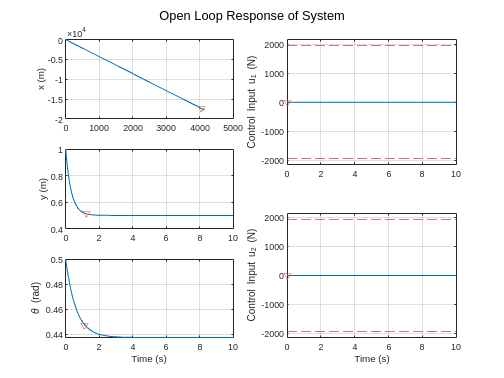

            yline(u2_max,'--','Color',[0.8 0.2 0.2])
            yline(-1*u2_max, '--','Color',[0.8 0.2 0.2])
            ylim([-u2_max-200 u2_max+200])
            
    % --Finding the settling times
        xx = lsiminfo(y(:,1),t);     % X values
        yy = lsiminfo(y(:,2),t);
        tt = lsiminfo(y(:,3),t);
        uu1 = lsiminfo(y(:,4),t);
        uu2 = lsiminfo(y(:,5),t);
    
    % --Making Table of values
        settling_times = [xx.TransientTime;
                          yy.TransientTime;
                          tt.TransientTime;
                          uu1.TransientTime;
                          uu2.TransientTime];
        var_names = {'X';'Y';'Theta';'U1';'U2'};
        T = table(settling_times,VariableNames="Settling Times (s)",RowNames = var_names);
        display(T)
    
    % --Plotting onto subplots
        idx = find(abs(t - xx.TransientTime) < 0.1);
        idx = min(idx);
        subplot(3,2,1)
        plot(t(idx),y(idx,1),'V')

Design 1:

T = 6×1 table
    Poles
    _____
      -2 
      -4 
      -6 
      -8 
     -10 
     -12 

T = 5×1 table
             Settling Times (s)
             __________________
    X              2.0192      
    Y              1.0225      
    Theta          1.9027      
    U1            0.97312      
    U2            0.87924      

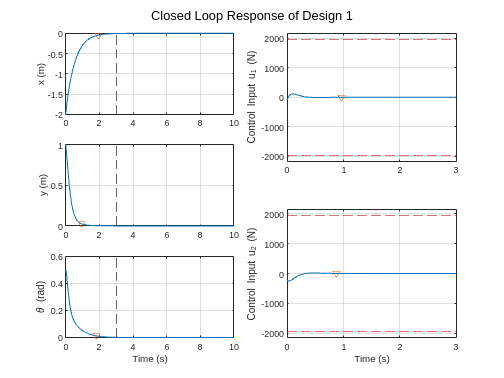

T = 2×2 table
          Max Actuator Authority (N)    Maximum Control Input (N)
          __________________________    _________________________
    U1                1960                       108.68          
    U2              1941.9                       246.55          

Design 2:

T = 6×1 table
     Poles 
    _______
    -4+4i  
    -4-4i  
    -4+2.4i
    -4-2.4i
    -4+0.8i
    -4-0.8i

T = 5×1 table
             Settling Times (s)
             __________________
    X              1.2989      
    Y              1.2498      
    Theta          1.7206      
    U1             1.0654      
    U2             1.0731      

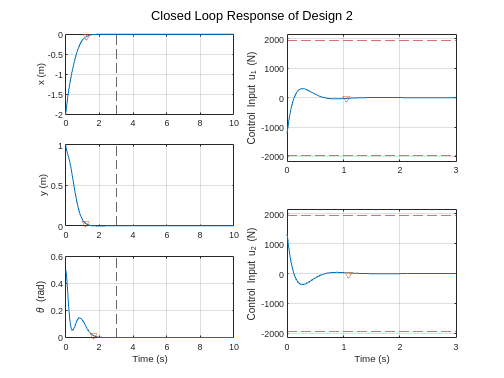

T = 2×2 table
          Max Actuator Authority (N)    Maximum Control Input (N)
          __________________________    _________________________
    U1                1960                       1209.9          
    U2              1941.9                       1330.8          

Design 3:

T = 6×1 table
       Poles   
    ___________
    -2.83+2.83i
    -2.83-2.83i
    -2.75+2.9i 
    -2.75-2.9i 
    -3.85+1i   
    -3.85-1i   

T = 5×1 table
             Settling Times (s)
             __________________
    X              1.3919      
    Y              1.4344      
    Theta          1.9452      
    U1             1.4841      
    U2             2.0882      

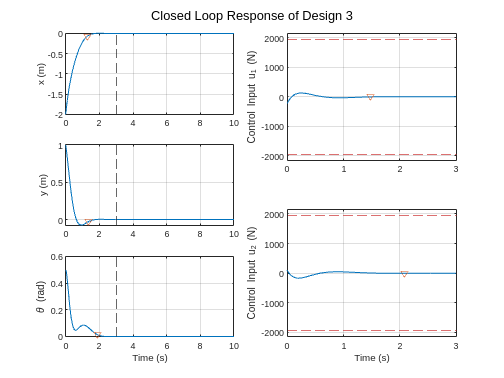

T = 2×2 table
          Max Actuator Authority (N)    Maximum Control Input (N)
          __________________________    _________________________
    U1                1960                       228.32          
    U2              1941.9                       168.47          

        xline(3,'--')
    
        idx = find(abs(t - yy.TransientTime) < 0.1);
        idx = min(idx); 
        subplot(3,2,3)
        plot(t(idx),y(idx,2),'V')
        xline(3,'--')
    
        idx = find(abs(t - tt.TransientTime) < 0.1);
        idx = min(idx);
        subplot(3,2,5)
        plot(t(idx),y(idx,3),'V')
        xline(3,'--')
    
        idx = find(abs(t - uu1.TransientTime) < 0.01);
        idx = min(idx);
        subplot(2,2,2)
        plot(t(idx), y(idx,4),'V')
    
        idx = find(abs(t - uu2.TransientTime) < 0.01);
        idx = min(idx);
        subplot(2,2,4)
        plot(t(idx), y(idx, 4), 'V')
    % --Max control inputs 
        u_max_1 = [max(abs(y(:,4))); max(abs(y(:,5)))];
        u_sat = [u1_max; u2_max];
        var_names = {'Max Actuator Authority (N)','Maximum Control Input (N)'};
        row_names = {'U1','U2'};
        T = table(u_sat,u_max_1,'VariableNames',var_names,'RowNames',row_names)
end